clear, close all, clc

Vi ønsker en regressionsmodel, hvor den går gennem (0,0). Modellen er Y = beta*x + epsilon. Antag, at vi har n par data, (x1,y1) ... (xn,yn).

Opgave a)

Find least-squares estimatet af beta.

% Fra løsningen; taget ud fra epsilon og afledt mht. beta
% beta = sum(yi*xi)/sum(xi^2)

Opgave b)

Fit modellen til data fra opgave 11-10. Plot den fittede model over data.

load('dataset_problem_11_10.mat')
X = data(:,2)

X =     0.1900
    0.1500
    0.5700
    0.7000
    0.6700
    0.6300
    0.4700
    0.7000
    0.6000
    0.7800


y = data(:,1)

y =     4.4000
    6.6000
    9.7000
   10.6000
   10.8000
   10.9000
   11.8000
   12.1000
   14.3000
   14.7000


b = regress(y,X)

b = 21.0315

fitx = linspace(min(X),max(X),100);
fity = b*fitx;
scatter(X,y,'k','filled')

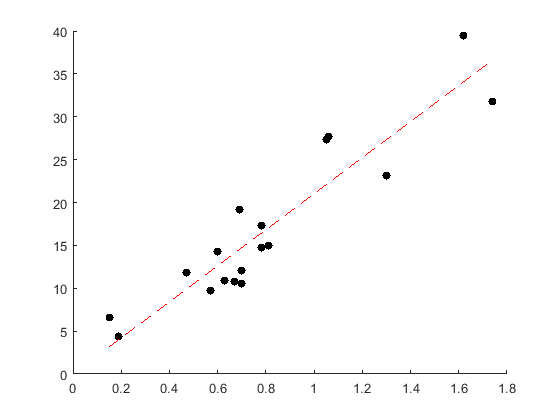

hold on
plot(fitx,fity,'r--')